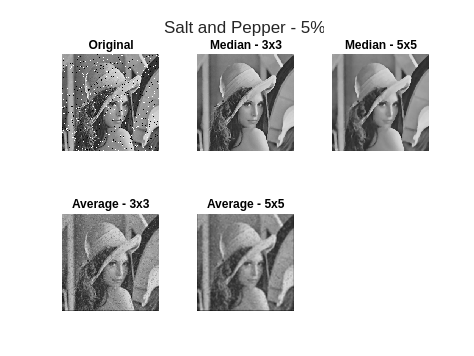

I = imread("lena_gray_256.tif");

% Adding salt and pepper noises
I1 = imnoise(I, 'salt & pepper',0.05);
I2 = imnoise(I,'salt & pepper',0.10);
I3 = imnoise(I,'salt & pepper',0.20);

% Applying filters to the images
apply_filters(I1, "Salt and Pepper - 5%");

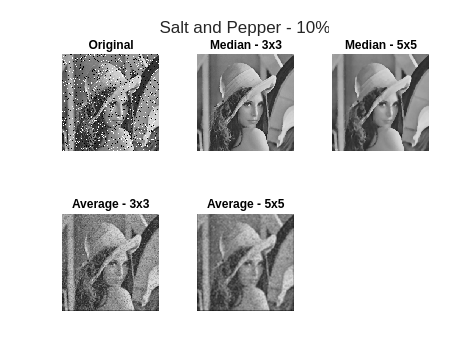

apply_filters(I2, "Salt and Pepper - 10%");

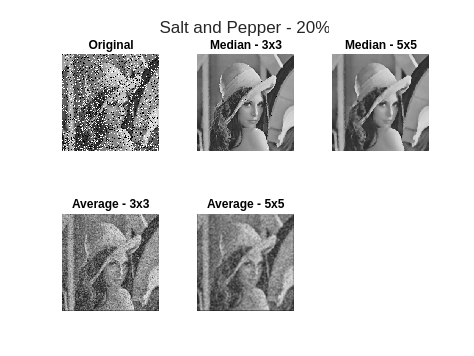

apply_filters(I3, "Salt and Pepper - 20%");

function apply_filters(im, t)
    figure;
    l = tiledlayout(2, 3);
    title(l, t);

    nexttile;
    imshow(im);
    title("Original");

    m1 = medfilt2(im, [3 3]);
    nexttile;
    imshow(m1);
    title("Median - 3x3");

    m2 = medfilt2(im, [5 5]);
    nexttile;
    imshow(m2);
    title("Median - 5x5");

    filter = fspecial('average', [3, 3]);
    avg3 = imfilter(im, filter);
    nexttile
    imshow(avg3)
    title("Average - 3x3")

    filter = fspecial('average', [5, 5]);
    avg5 = imfilter(im, filter);
    nexttile
    imshow(avg5)
    title("Average - 5x5")
end